# Linear Control Design II - Group Work Problem Module 17

## **Description**

The dynamics of a wind turbine operating in the full load region reads


$$J_r\dot{\omega}_r = \frac{1}{2}\rho A R \mathrm{CP}(\beta,\lambda) \frac{v^2}{\lambda} - K_{d}\theta - B_{d}\left(\omega_r - \frac{\omega_g}{N_g}\right)$$



$$J_g\dot{\omega}_g = \frac{K_{d}}{N_g}\theta + \frac{B_{d}}{N_g}\left(\omega_r - \frac{\omega_g}{N_g}\right) - T_g$$



$$\dot{\theta} = \omega_r - \frac{\omega_g}{N_g}$$



$$y_1 = \omega_r$$



$$y_2 = P_e = \omega_g T_g$$


where all quantities of interest are defined Group work Module 1. Based on the operating point and linearized model determined in Module 9 P1 and P2 address the following problems.

## Problems

**P1    **Set the generator torque to its constant operating point, $T_g = T_{g,OP}$. Under the assumption that the system state is fully accessible (i.e. all state variables are available to the controller), design a discrete time full state feedback controller with integral action that uses the pitch angle $\beta$ to regulate the rotor angular speed $\omega_r$ to its nominal value $\omega_{r,OP}$ despite variations in wind speed. The controller should assign eigenvalues such that 

- the settling time of $\omega_r$ to step changes in wind speed of $\pm2\;\mathrm{m/s}$ is between 0.5 and 1 second

- the response of $\omega_r$ to step changes in wind speed is not critically damped

**P1.Solution**

The system is single input single output because the generator torque is set to be at its constant operating value. It is assumed that the wind speed is piecewise constant around the steady state value. Hence only an integrator is needed.

clear all
close all
clc

% Get relevant parameters for the wind turbine. Still need to define x0 and vOP in the Simulink model
load('relevantWindTurbineParameters.mat')
% Get the operating point and the linearized model from Module 10 P1 and P2
load('LinearModel.mat')

% Set Simulation Time
TIME_SIM = 25;

Dv = 2; %[m/s]

% Adapt the system matrices to match the requirements (SISO)
Bb = Bb(:,1); % Removing Tg
CcO = Cc; % Cc for problem 4
Cc = Cc(1,:); % Only measure wr
Dd = Dd(:,1);

% Find eigenvalues and asses asymptotical stability
lbd = eig(Aa)

lbd =   -0.2071 + 0.0000i
  -0.6797 +13.6692i
  -0.6797 -13.6692i


disp('The system in asymptotically stable')

The system in asymptotically stable



% time constants
tau = -1./lbd(imag(lbd)==0)

tau = 4.8291


% natural frequencies and damping ratios
wn = sqrt(real(lbd(2))^2+imag(lbd(2))^2)

wn = 13.6861


z = -real(lbd(2))/wn

z = 0.0497


% Assess Controllablity
Mc = ctrb(Aa,Bb);
if rank(Mc) == rank(Aa)
    disp('The system is controllable')
else
    disp('The system is not controllable')
end

The system is controllable



% Choosing a sampling time for the discrete controller based on openloop
% dynamics and closed loop requirements.
T = 2*pi/wn;
T_settling_min = 0.5;
tau_settling_min = 0.5/5; % assuming a first order system behaviour of the closed loop response

Ts = min([tau(1)/10 T/10 tau_settling_min/10]) % sampling time

Ts = 0.0100



[Ff,Gg] = c2d(Aa,Bb,Ts) % Discretize the LTI continuous system

Ff =     0.9960    0.0000   -0.1451
    2.0182    0.9792  165.8303
    0.0099   -0.0001    0.9907


Gg =    -0.0110
   -0.0097
   -0.0001


For integral control, we have to augment the system first. Note that the equations (4.102)-(4.107) in the book has to be modified slightly, as the derivation assumes that Ts=1.


% Augment system matrices
Fau = [Ff zeros(size(Aa,1),size(Cc,1));
       -Cc*Ts eye(size(Cc,1))]

Fau =     0.9960    0.0000   -0.1451         0
    2.0182    0.9792  165.8303         0
    0.0099   -0.0001    0.9907         0
   -0.0100         0         0    1.0000



% Augment Gg
Gau = [Gg;
       zeros(size(Gg,2),size(Cc,1))]

Gau =    -0.0110
   -0.0097
   -0.0001
         0


% Assess Controllablity - We have to make sure that the new augmented
% system is fully controllable
Mc = ctrb(Fau,Gau);
if rank(Mc) == rank(Fau)
    disp('The system is controllable')
else
    disp('The system is not controllable')
end

The system is controllable


Now we can start making the controller with full state feedback and integral control described in chapter 5

%  ---- Desired characteristics for the closed loop system ---- 
% Not critically damped refers to 2nd order systems with damping above or
% below 1. We accept a little bit of overshoot but not to much thus damping
% is chosen to be 1/sqrt(2) < zeta < 1 - here zeta = 0.8 is chosen.

% The settling time should be between 0.5-1s for step changes in wind speed
% of +-2m/s. The speed of the response in a 2nd order system is related to
% the natural frequency and damping ratio: Tsettling = 4/(zeta*omega_n) (approximately). 

% We need to find 4 eigenvalues (3 for the original system and one for the integrator) and the dominant complex pair
% are based on the design requirements and the others are chosen a bit faster. 

% First natural frequency and damping factor
Tsettling = 0.75; % Settling time
zeta_cl_1 = 0.65;

wn_cl_1 = 4/(zeta_cl_1*Tsettling); 
% Corresponding eigenvalue (alpha +- j*beta)
alpha_1 = -wn_cl_1*zeta_cl_1;
beta_1 = sqrt(wn_cl_1^2 - alpha_1^2);

% Second natural frequency and damping factor
wn_cl_2 = wn_cl_1*1.2; % Choose the second natural frequency to be bigger than the first one.
zeta_cl_2 = 0.8; %zeta_cl_1; % Choose the same damping here

% Corresponding eigenvalues
alpha_2 = -wn_cl_2*zeta_cl_2;
beta_2 = sqrt(wn_cl_2^2 - alpha_2^2);


% Collect desired closed loop eigenvalues for the continuous system
lambda_ct_des = [alpha_1+1i*beta_1 alpha_1-1i*beta_1 alpha_2+1i*beta_2 alpha_2-1i*beta_2];

% Convert to discrete eigenvalues
lambda_dt_des = exp(lambda_ct_des*Ts)   

lambda_dt_des =    0.9462 + 0.0591i   0.9462 - 0.0591i   0.9226 + 0.0546i   0.9226 - 0.0546i


% Calculate gains for full state feedback.
% acker() because we have a SISO system. Calculate for non-augmented system.
K1 = acker(Fau, Gau, lambda_dt_des);
K_FSF = K1(1:3) % Gain for full state feedback

K_FSF =   -20.4400    0.1119  -62.8482


Ki = -K1(4) % Gain for integrator

Ki = -30.2224


% Make sure that the closed loop system has stable eigenvalues (between 0 and 1).
eig(Fau-Gau*K1)

ans =    0.9226 + 0.0546i
   0.9226 - 0.0546i
   0.9462 + 0.0591i
   0.9462 - 0.0591i


**P2    **Implement the open loop linear system and the designed control system in Simulink. Evaluate the performance of your controller against the given requirements in response to wind speed step changes of $\pm 2\, \mathrm{m/s}$.

**Solution:**

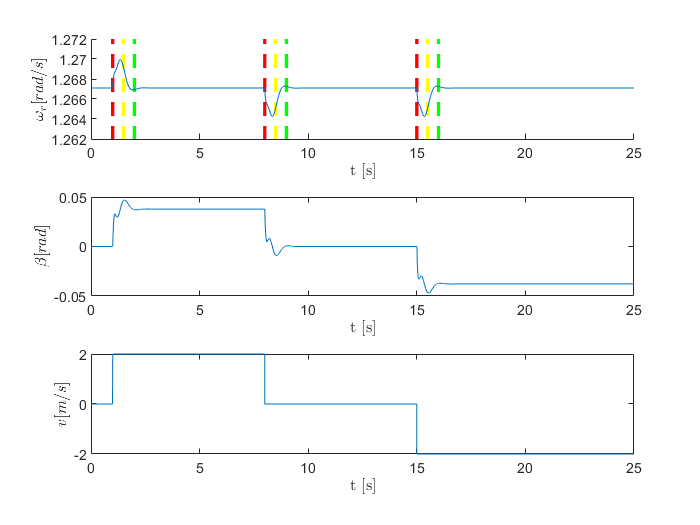

% Set Simulation Parameters

% Integrator step size in Simulink
STEP_SIZE = Ts/50;

% Sequence of disturbance i.e. windspeed changes
v_in = [zeros(floor(1/STEP_SIZE),1); Dv*ones(floor(7/STEP_SIZE),1); zeros(floor(7/STEP_SIZE),1); -Dv*ones(floor(7/STEP_SIZE),1)];
t = 0:STEP_SIZE:TIME_SIM;

% Pad with -Dv at end
pad = length(t) - length(v_in);
v_in = [v_in; -Dv*ones(pad,1)];

% Find indiceses of windspeed changes and +4s and +6s (for plots)
stCh = find(diff(v_in) ~= 0);
ch1 = t(stCh(1));
ch14 = t(stCh(1)+floor(0.5/STEP_SIZE));
ch16 = t(stCh(1)+floor(1/STEP_SIZE));
ch2 = t(stCh(2));
ch24 = t(stCh(2)+floor(0.5/STEP_SIZE));
ch26 = t(stCh(2)+floor(1/STEP_SIZE));
ch3 = t(stCh(3));
ch34 = t(stCh(3)+floor(0.5/STEP_SIZE));
ch36 = t(stCh(3)+floor(1/STEP_SIZE));
w_OPup = w_OP*1.01;
w_OPlow = w_OP*0.99;

[~,~,yout] = sim('p2_linearWindTurbineModel',[0 TIME_SIM],[],[t' v_in]);

% Plot wr, windspeed and input
figure
subplot(3,1,1)

line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
hold on
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
plot(t,yout(:,1))
ylim([1.262 1.272])
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
subplot(3,1,2)
plot(t,yout(:,3))
hold on
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')
subplot(3,1,3)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

The red dashed lines marks the time instants where the step changes in the wind speed kick in. After 0.5 seconds transient $\omega_r$ settles back almost to the operating value (yellow dashed  lines). After 1 seconds since the step change takes place $\omega_r$ is back to the required value. The response is also not critically damped but not very underdamped either which can be seen in the small overshoot between the yellow and green lines.

Plotting the input $\beta$ gives a feeling of the physical feasability of the controller. When designing the controller one should always keep in mind the constraints introduced by the actuator.

% Save yout structure to further plots
youtP2 = yout;
youtP2(:,2) = youtP2(:,2) + v_OP;
youtP2(:,3) = youtP2(:,3) + beta_OP;

**P3    **Implement the designed controller on the Simulink nonlinear model of the wind turbine provided in Module 9 and repeat the simulations performed in P2. Compare and discuss the performance of the control system on the linearized and nonlinear model.

**Solution:**

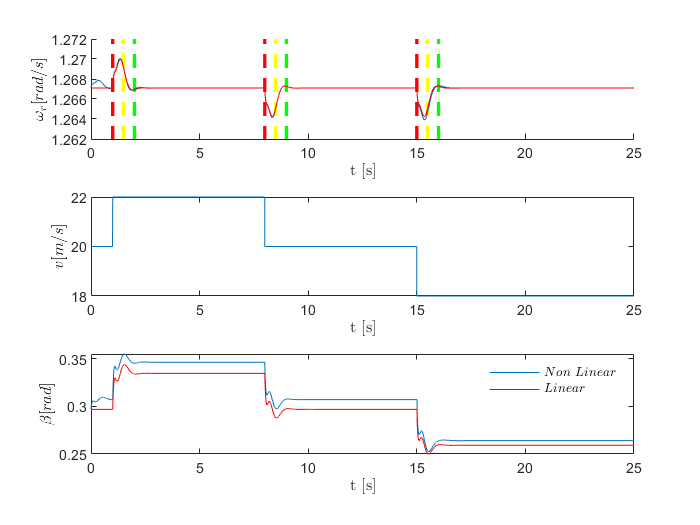

v_inNonLinear = v_in+v_OP;

[~,~,yout] = sim('p3_windTurbineModel.slx',[0 TIME_SIM],[],[t' v_inNonLinear]);
youtP3 = yout;

% Plot wr, windspeed and input
figure
subplot(3,1,1)

line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
hold on
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
plot(t,yout(:,1))
plot(t,youtP2(:,1),'Color','r')
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
ylim([1.262 1.272])
subplot(3,1,2)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')
subplot(3,1,3)
plot(t,yout(:,3))
hold on
plot(t,youtP2(:,3),'Color','r')
hold off
leg1 = legend('$Non \ Linear$','$Linear$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

**P4    **Since only the rotor angular velocity and the electrical power are measured the controller designed in P1 cannot be implemented in reality unless an observer is also designed to estimate the unmeasured state variable. Design a discrete time full order observer that provides the state estimates of the measured and unmeasured state variables. The estimation error dynamics should settle to zero within 0.1 and 0.2 seconds.

**Solution:**

% The observer system estimates 3 states, which means that we have to
% design 3 eigenvalues with the desired characteristics for the estimation
% error dynamics
% We choose a complex pair of eigenvalues and a real eigenvalue

% For the real eigenvalue we just need to define the time constant tau
% based on the desired settling time, knowing that T_settling =~ 4*tau
t_settling_obs_1 = 0.15;
tau_obs_1 = t_settling_obs_1/4;
lambda_obs_1 = -1/tau_obs_1;

% For the complex pair, we can choose a slightly faster response, 
% within the limits of the specifications
t_settling_obs_2 = 0.1;
% knowing that the settling time for complex eigenvalues can be
% approximated as T_settling = -4/alpha, we find
alpha_obs_2 = -4/t_settling_obs_2; %-4
% Now, we want the damping factor to be larger than 1/sqrt(2) =~ 0.7 
% to avoid oscllatory behavior. We choose a value of 0.8
zeta_obs_2 = 0.8;
% With that, we can find the corresponding eigenvalue (alpha +- j*beta)
wn_obs_2 = -alpha_obs_2/zeta_obs_2;
beta_obs_2 = sqrt(wn_obs_2^2 - alpha_obs_2^2);

% Convert to discrete eigenvalues
lambda_ct_Obs_des = [lambda_obs_1 alpha_obs_2+1i*beta_obs_2 alpha_obs_2-1i*beta_obs_2];

lambda_dt_Obs_des = exp(lambda_ct_Obs_des*Ts)   

lambda_dt_Obs_des =    0.7659 + 0.0000i   0.6404 + 0.1981i   0.6404 - 0.1981i


% Find Observer gain matrix
L = (place(Ff',CcO',lambda_dt_Obs_des)')

L =     0.2307   -0.0097
    1.2545   16.9230
    0.0083    0.0215


% Make sure that the observer dynamics is stable and matches the desired one
check1 = eig(Ff-L*CcO)

check1 =    0.7659 + 0.0000i
   0.6404 + 0.1981i
   0.6404 - 0.1981i


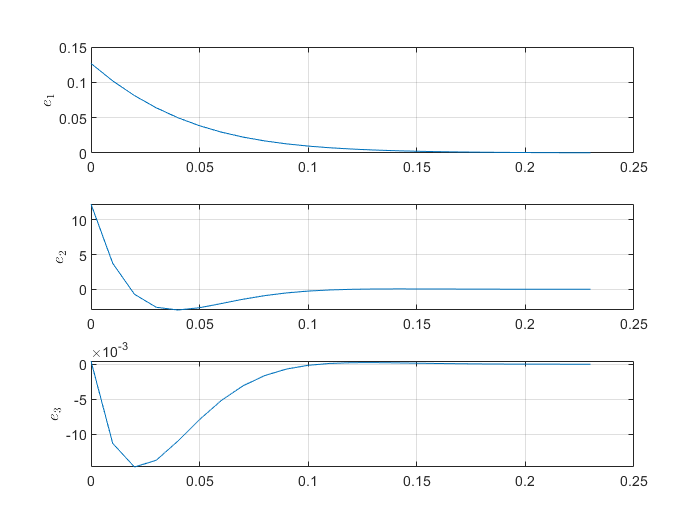

% Check that the estimation error dynamics converges to zero within 0.1 s and 0.2 s

tP4 = 0:Ts:1.5; %Simulate only for the needed amount of time

xe0 = 0.1*xOP;
Fe = Ff-L*CcO;
Ge = zeros(size(Ff,1),1);
Ce = eye(size(Ff,1));
De = Ge;
sys = ss(Fe,Ge,Ce,De,Ts);

[e,te,~] = initial(sys,xe0);
figure
subplot(3,1,1)
plot(te,e(:,1))
ylabel('$e_1$','Interpreter','latex')
grid on
subplot(3,1,2)
plot(te,e(:,2))
ylabel('$e_2$','Interpreter','latex')
grid on
subplot(3,1,3)
plot(te,e(:,3))
ylabel('$t \ [s]$','Interpreter','latex')
ylabel('$e_3$','Interpreter','latex')
grid on

The plot above shows the estimation error zero-input response for 10 % initial bias in the states estimations. As required the estimation error settles to 0 within 0.1 and 0.2 s. Different design may lead to the same outcome.

**P5   **Implement the designed observer on the open loop linear model and evaluate its estimation performance around the operating point for step changes in pitch angle $\beta$ of $\pm 3 \;\mathrm{deg}$.

**Solution:**

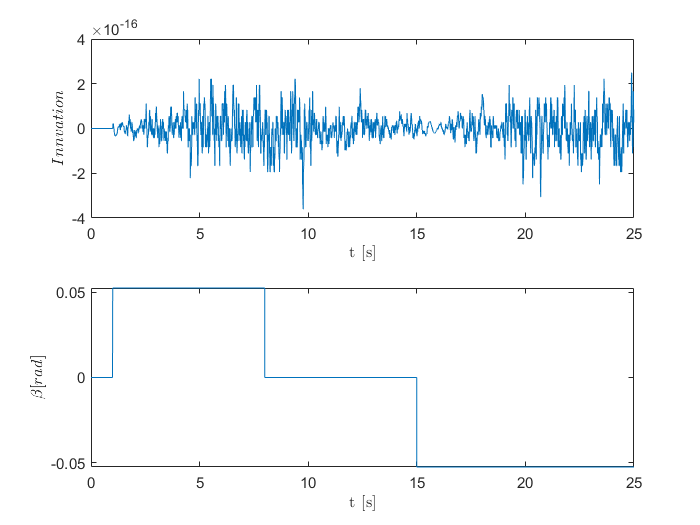

% Sequence of disturbance i.e. windspeed changes
DBeta = 3*pi/180; %[rad]
beta_in = [zeros(floor(1/STEP_SIZE),1); DBeta*ones(floor(7/STEP_SIZE),1); zeros(floor(7/STEP_SIZE),1); -DBeta*ones(floor(7/STEP_SIZE),1)];

% Pad with -DBeta at end
pad = length(t) - length(beta_in);
beta_in = [beta_in; -DBeta*ones(pad,1)];

% Find indiceses of windspeed changes and +4s and +6s (for plots)
stCh = find(diff(beta_in) ~= 0);
ch1 = t(stCh(1));
ch14 = t(stCh(1)+floor(0.5/STEP_SIZE));
ch16 = t(stCh(1)+floor(1/STEP_SIZE));
ch2 = t(stCh(2));
ch24 = t(stCh(2)+floor(0.5/STEP_SIZE));
ch26 = t(stCh(2)+floor(1/STEP_SIZE));
ch3 = t(stCh(3));
ch34 = t(stCh(3)+floor(0.5/STEP_SIZE));
ch36 = t(stCh(3)+floor(1/STEP_SIZE));
w_OPup = w_OP+0.005;
w_OPlow = w_OP-0.005;

[~,~,yout] = sim('p5_linearWindTurbineModel',[0 TIME_SIM],[],[t' beta_in]);
% yout = [xh1, xh2, xh2, inn1, inn2, x1, x2, x3]

figure
subplot(2,1,1)
plot(t,yout(:,4))
xlabel('t [s]','Interpreter','latex')
ylabel('$Innvation$','Interpreter','latex')
subplot(2,1,2)
plot(t,beta_in)
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

The innovations over $\omega_r$ measure the quality of the designed observer. The complete convergence occurs after 0.15 seconds and this fact might lead the reader thinking that the observer hasn't been correctly designed. Instead it is not the case since the innovations upper bound is  in the order of $10^{-16
}$ rad/s 

If this profile (innovation) is compared against the response of $\theta$ in the next plot (scroll down), one can see that they have the same shape. The fast oscillatory behavior of $\theta$ creates small errors in the innovation signal.

We can also visualize the true and estimated estates in the linear model and check that the observer converges to the true value 

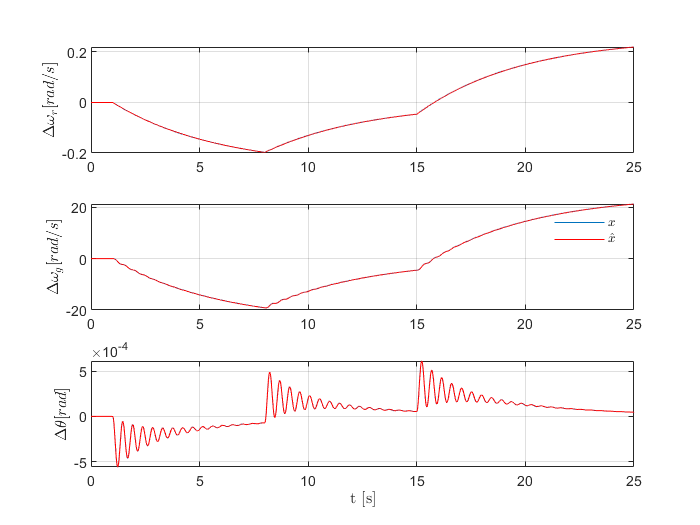

% Comparison of true and estimated states for the linear model
figure

subplot(3,1,1)
plot(t,yout(:,6))
hold on
plot(t,yout(:,1),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,7))
hold on
plot(t,yout(:,2),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,8))
hold on
plot(t,yout(:,3),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

Now let's simulate and plot the observer behavior on the non-linear model

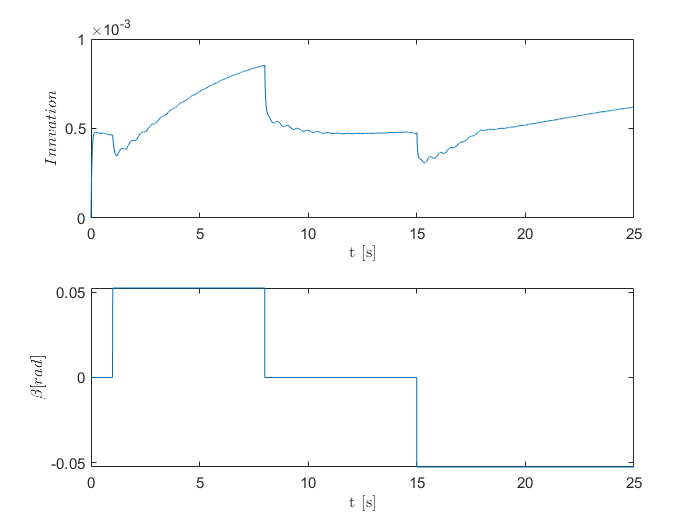

% Non-linear model
close all
[~,~,yout] = sim('p5_WindTurbineModel',[0 TIME_SIM],[],[t' beta_in]);
% yout = [xh1, xh2, xh2, inn1, inn2, w3, x1, x2, x3]
figure
subplot(2,1,1)
plot(t,yout(:,4))
xlabel('t [s]','Interpreter','latex')
ylabel('$Innvation$','Interpreter','latex')
subplot(2,1,2)
plot(t,beta_in)
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

For the non-linear system a small offset is present in the innovation

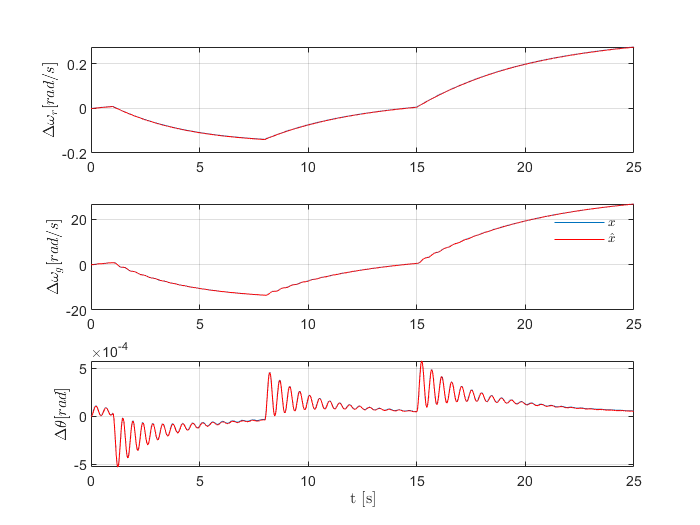

% Comparison of true and estimated states
figure


subplot(3,1,1)
plot(t,yout(:,7))
hold on
plot(t,yout(:,1),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,8))
hold on
plot(t,yout(:,2),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,9))
hold on
plot(t,yout(:,3),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

For the non-linear model, the observer still converges to the true states but with a small bias

**P6    **Now close the loop again around the linearized model by feeding the controller with the estimates provided by the observer and evaluate the control system performance against that obtained in P2.

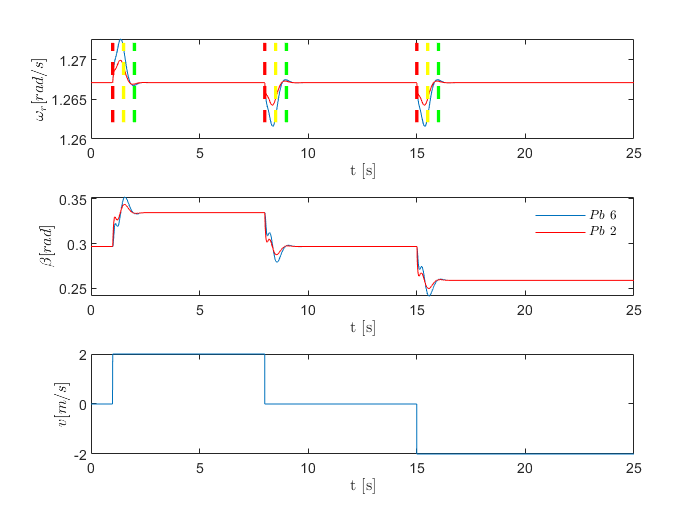

close all
[~,~,yout] = sim('p6_linearWindTurbineModel',[0 TIME_SIM],[],[t' v_in]);
% Plot wr, windspeed and input
figure,
subplot(3,1,1)
plot(t,yout(:,1))
hold on
plot(t,youtP2(:,1),'Color','r')
line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
subplot(3,1,2)
plot(t,yout(:,3)+beta_OP)
hold on
plot(t,youtP2(:,3),'Color','r')
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')
leg1 = legend('$Pb \ 6$','$Pb \ 2$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
subplot(3,1,3)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

Compared to **P2** the architecture has overall similar performance. Anyways in **P6 **$\omega_r$ shows larger overshoots which require a slightly more intense control effort to compensate for. This is not surprising since the observer has no knowledge about the disturbance and needs the integrator compensating for it before it can return accurate states estimations.

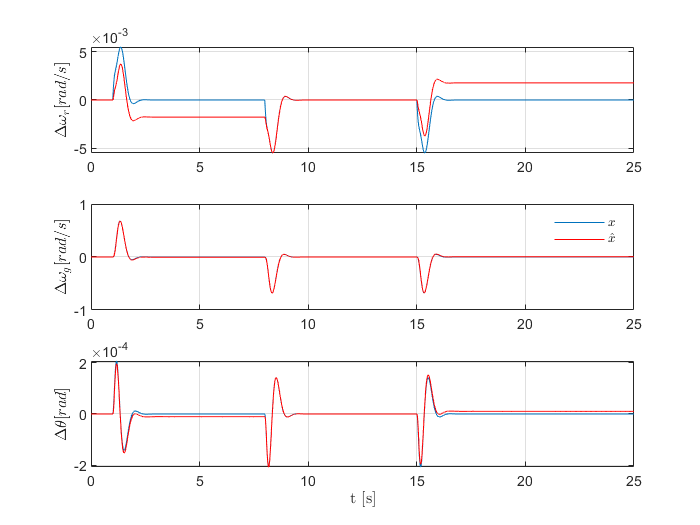

% Now compare the state estimates with the actual state

figure

subplot(3,1,1)
plot(t,yout(:,4))
hold on
plot(t,yout(:,7),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,5))
hold on
plot(t,yout(:,8),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,6))
hold on
plot(t,yout(:,9),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

**P7**    Last, close the loop around the nonlinear system with the controller and observer and compare the performance against that obtained in P3

[~,~,yout] = sim('p7_windTurbineModel',[0 TIME_SIM],[],[t' v_inNonLinear]);

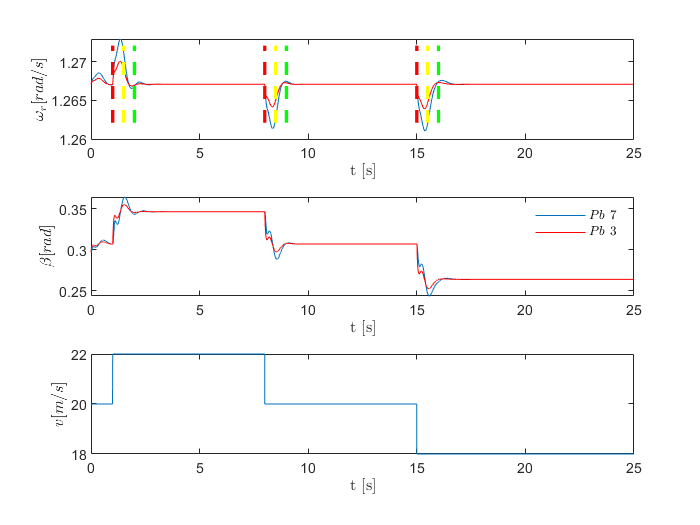

% Plot wr, windspeed and input
figure,
subplot(3,1,1)
plot(t,yout(:,1))
hold on
plot(t,youtP3(:,1),'Color','r')
line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
subplot(3,1,2)
plot(t,yout(:,3)+beta_OP)
hold on
plot(t,youtP3(:,3),'Color','r')
hold off
leg1 = legend('$Pb \ 7$','$Pb \ 3$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')
subplot(3,1,3)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

Once again the observer based full state feedback with integral action performs slightly worse though it still respects the requirements. The reasons for performance degradation can be found on the unmodelled disturbance within the observer.

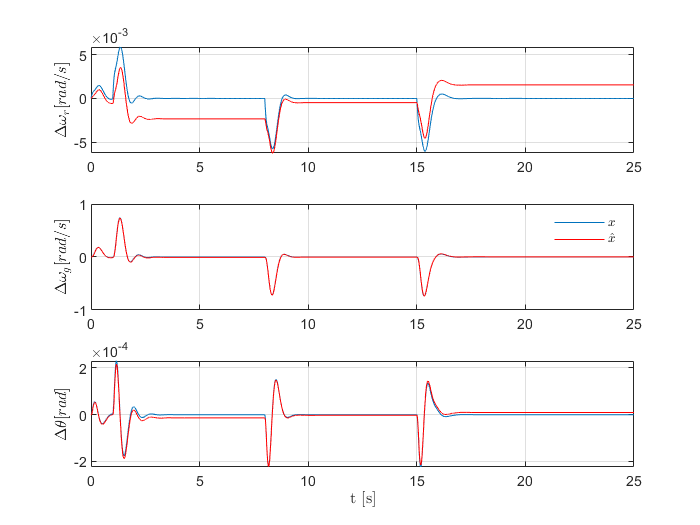

% Now compare the state estimates with the actual state

figure

subplot(3,1,1)
plot(t,yout(:,4))
hold on
plot(t,yout(:,7),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,5))
hold on
plot(t,yout(:,8),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,6))
hold on
plot(t,yout(:,9),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off